clear
K = .2; J = 100;
It = -J/(K - 1);
I = [It,It,J]

I =    125   125   100


k = (I(1)-I(3))/I(1)

k =    0.200000000000000


omega = [.1;.15;.3]

omega =    0.100000000000000
   0.150000000000000
   0.300000000000000


e = [0.3510
0.0554
-0.4127
0.8387]

e =    0.351000000000000
   0.055400000000000
  -0.412700000000000
   0.838700000000000


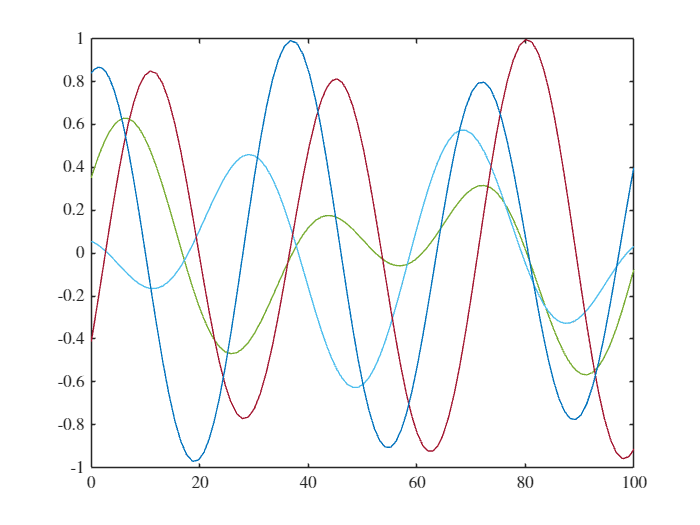


x0 = [e;omega];
t = [0,100];
[t,x] = ode45(@(t,x) f(t,x,I),t,x0);
e = x(:,1:4);
wt = x(:,5:7);

w1_0 = 0.1; w2_0 = 0.15; w3_0 = 0.3; Kw = .2;
w1 = @(t) w1_0 * cos(Kw * w3_0 * t) + w2_0 * sin(Kw * w3_0 * t);
w2 = @(t) w2_0 * cos(Kw * w3_0 * t) - w1_0 * sin(Kw * w3_0 * t);
w3 = @(t) w3_0;
w = @(t) [w1(t); w2(t); w3(t)]; % angular velocity in the B-frame

[t,e2] = ode45(@(t,bEn) KDE_EP(t,bEn,w(t)),t,e(1,:));

plot(t,e)
hold on
plot(t,e2)

function dxdt = f(t,x,I)
    dxdt(1:4,1) = KDE_EP(t,x(1:4),x(5:7));
    dxdt(5:7,1) = [(I(2)- I(3))/I(1)*x(6)*x(7);
                   (I(3)- I(1))/I(2)*x(7)*x(5);
                   (I(1)- I(2))/I(3)*x(6)*x(5)];
end
function dedt = KDE_EP(t,e,w)
dedt(1:3) = 1/2 * (e(4)*w + cross(e(1:3),w));
dedt(4) = -1/2*dot(e(1:3),w);
dedt = dedt';
end